## 定积分的求解

### 法一：基于辛普森法则逼近

例1.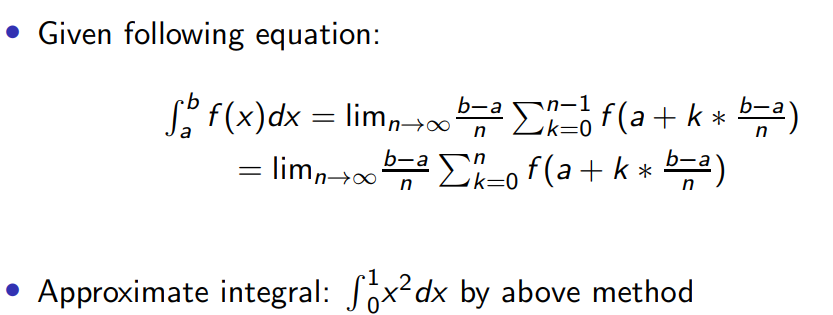

n=128%n越大，left和right越近

n = 128

x=0:1/n:1%a~b,n份

x =          0    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344    0.2422    0.2500    0.2578    0.2656    0.2734    0.2812    0.2891    0.2969    0.3047    0.3125    0.3203    0.3281    0.3359    0.3438    0.3516    0.3594    0.3672    0.3750    0.3828


left_sum=0;right_sum=0;
for i=1:n
left_sum=left_sum+x(i)^2*(1/n);
right_sum=right_sum+x(i+1)^2*(1/n);
end
left_sum

left_sum = 0.3294

right_sum

right_sum = 0.3372

例2.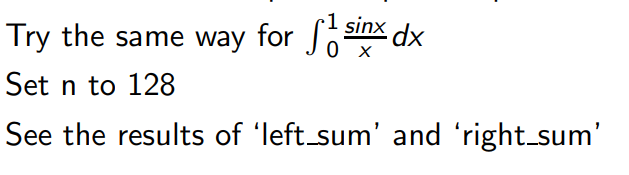

n=128

n = 128

x=0:1/n:1;
left_sum=0;right_sum=0;
for i=1:n
left_sum=left_sum+sin(x(i))/x(i)*(1/n);
right_sum=right_sum+sin(x(i+1))/x(i+1)*(1/n);
end
left_sum

left_sum = NaN

right_sum

right_sum = 0.9455

### 法二：int(f(x),x,a,b)

a、b为下限、上限

例1

.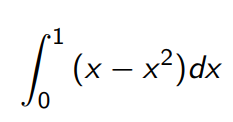

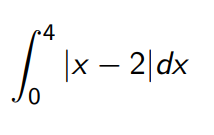

syms x
int((x-x^2),x,0,1)

$$ans = \frac{1}{6}$$

int(abs(x-2),x,0,4)

$$ans = 4$$

### 法三：quad

#### quad(inline('f(x)','x'),a,b)

#### quad(@(x)f(x),a,b)

x向量形式

quad(inline('sin(x)./x','x'),0,1)

ans = 0.9461

quad(@(x)sin(x)./x,0,1)

ans = 0.9461

## 不定积分

### int(f(x),x)

f(x)为原函数

例1.

syms x
int(x^2*(1-x^3)^5,x)

$$ans = -\frac{x^{18}}{18}+\frac{x^{15}}{3}-\frac{5\,x^{12}}{6}+\frac{10\,x^{9}}{9}-\frac{5\,x^{6}}{6}+\frac{x^{3}}{3}$$


int(exp(-2*x)*sin(3*x),x)

$$ans = -\frac{{\mathrm{e}}^{-2\,x}\,\left(3\,\cos\left(3\,x\right)+2\,\sin\left(3\,x\right)\right)}{13}$$


int(atan(x)*x^2,x)

$$ans = \frac{\log\left(x^{2}+1\right)}{6}+\frac{x^{3}\,\mathrm{atan}\left(x\right)}{3}-\frac{x^{2}}{6}$$


int (sin(x)/x,x)

$$ans = \mathrm{sinint}\left(x\right)$$

## 积分练习1.

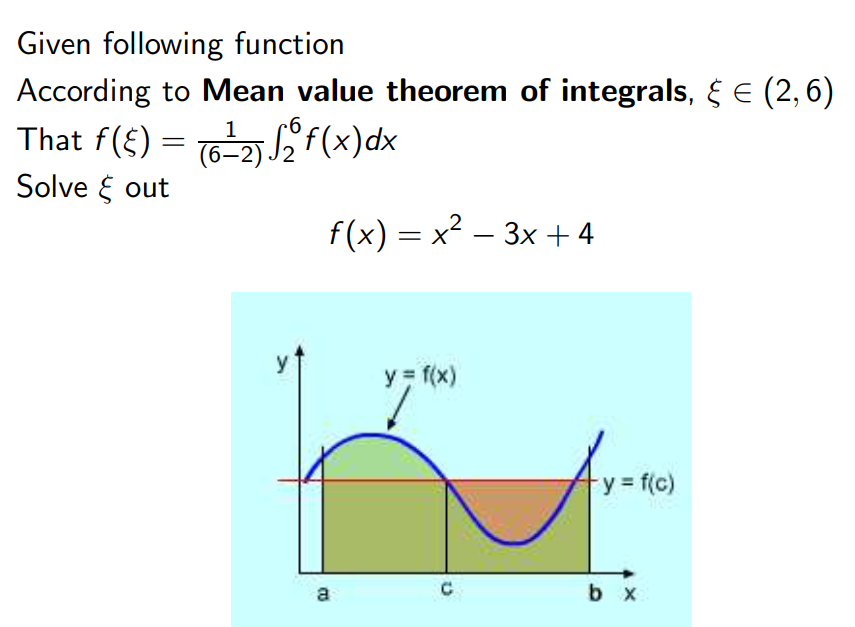

a=int(1/4*(x^2-3*x+4),x,2,6)

$$a = \frac{28}{3}$$

xi=solve((x^2-3*x+4)==a)

$$xi = \left(\begin{array}{c} \frac{3}{2}-\frac{\sqrt{3}\,\sqrt{91}}{6}\\ \frac{\sqrt{3}\,\sqrt{91}}{6}+\frac{3}{2} \end{array}\right)$$

%or
xi=roots([1,-3,4-a])

$$xi = \left(\begin{array}{c} \frac{3}{2}-\frac{\sqrt{3}\,\sqrt{91}}{6}\\ \frac{\sqrt{3}\,\sqrt{91}}{6}+\frac{3}{2} \end{array}\right)$$

## 3D图的绘制

### 1.plot3(x,y,z,'s')

### 2.ezplot3('x(t)','y(t)','z(t)',[t1,t2])

例1.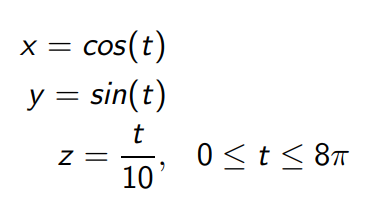

#### set(fig1,'Color','r')--设置图像颜色

fig1=ezplot3('cos(t)','sin(t)','t/10',[0,8*pi])

fig1 =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×300 double]
              YData: [1×300 double]
              ZData: [1×300 double]

  显示 所有属性


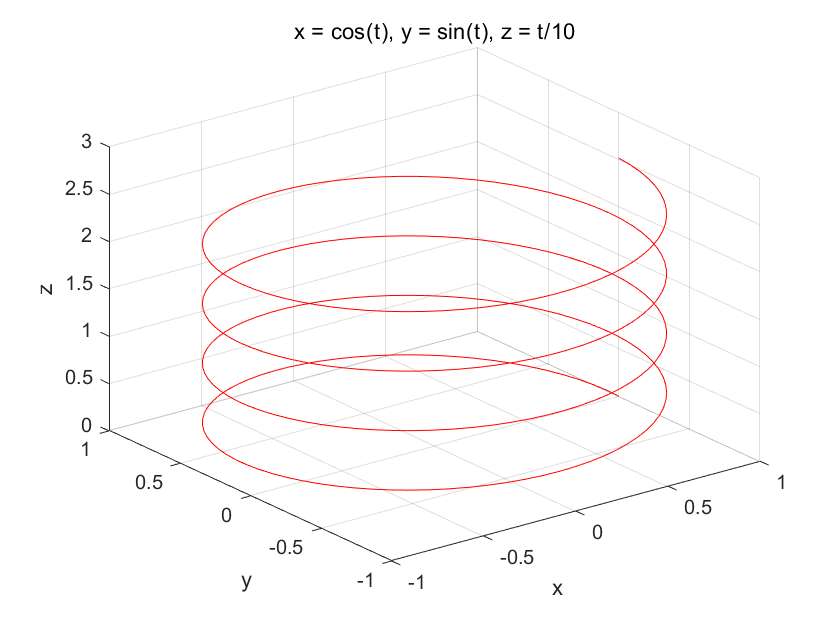

set(fig1,'Color','r')

### 3.mesh(X,Y,Z)

### 4.surf(X,Y,Z)

使用mesh和surf前，需用meshgrid(x,y)创建二维网格坐标

例1.

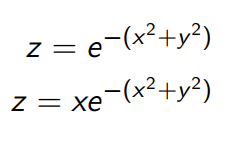

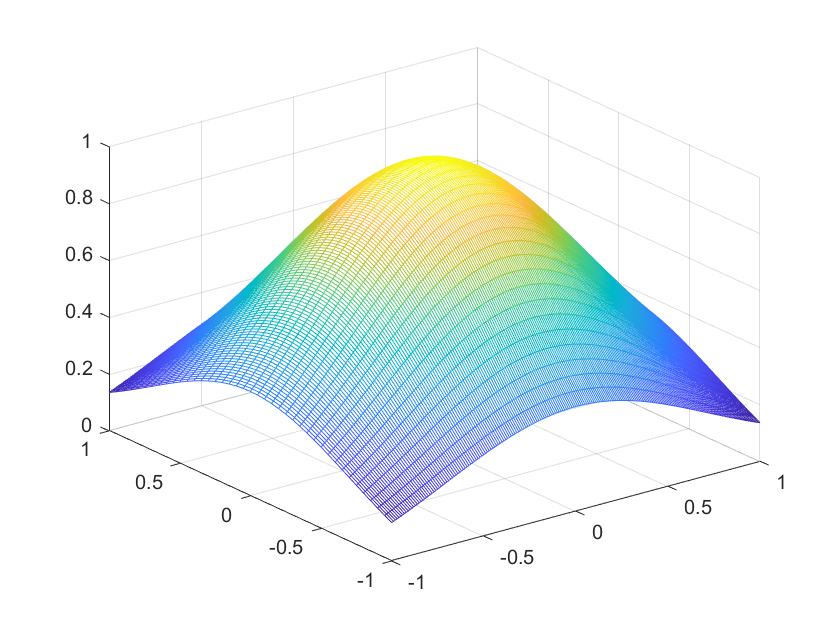

x=-1:0.01:1;y=-1:0.05:1;
[X,Y]=meshgrid(x,y);
Z=exp(-X.^2-Y.^2);
mesh(X,Y,Z)

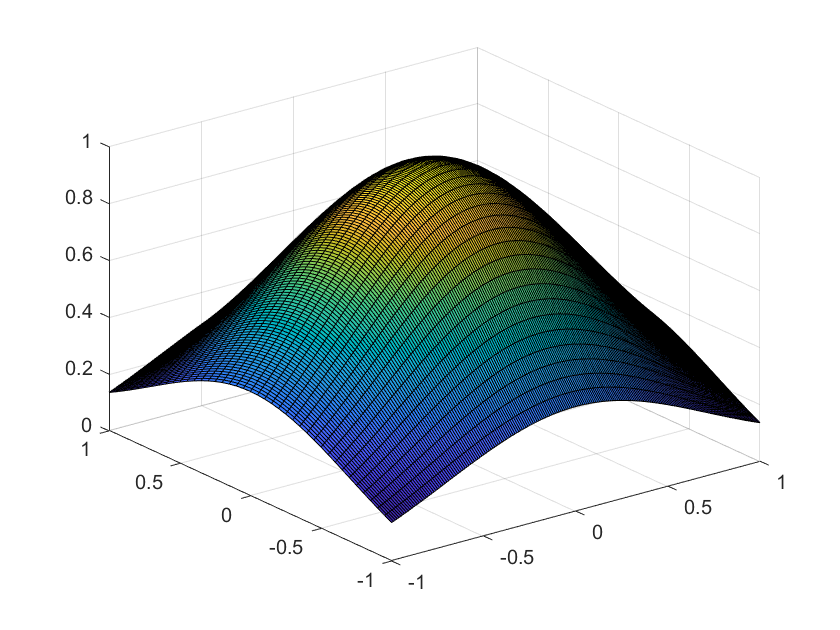

surf(X,Y,Z)

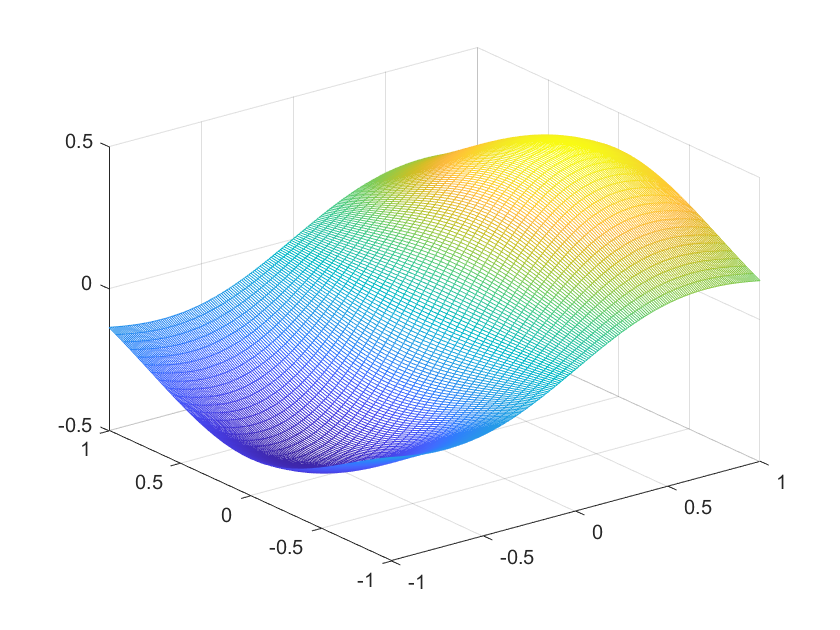


x=-1:0.01:1;y=-1:0.05:1;
[X,Y]=meshgrid(x,y);
Z=X.*exp(-X.^2-Y.^2);
mesh(X,Y,Z)

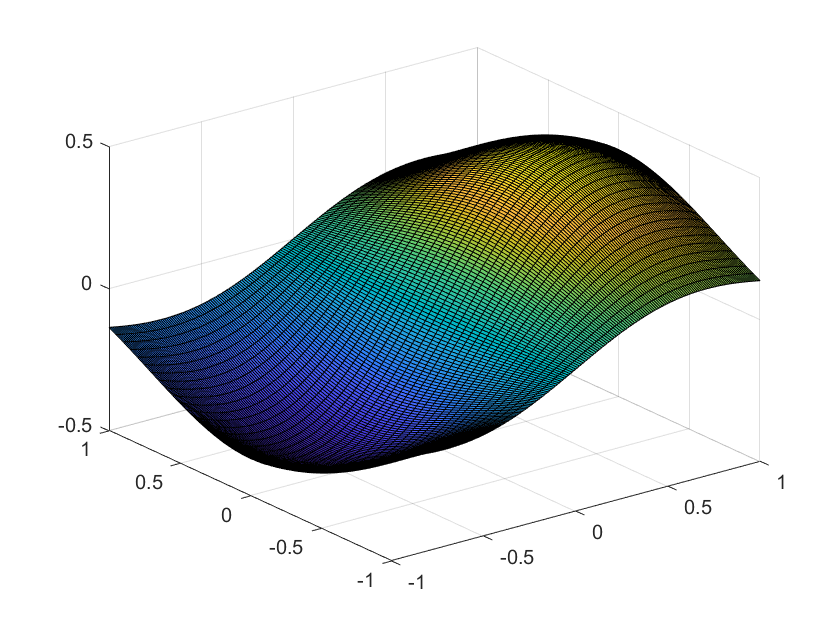

surf(X,Y,Z)

例2.

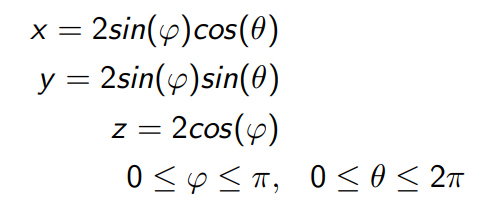

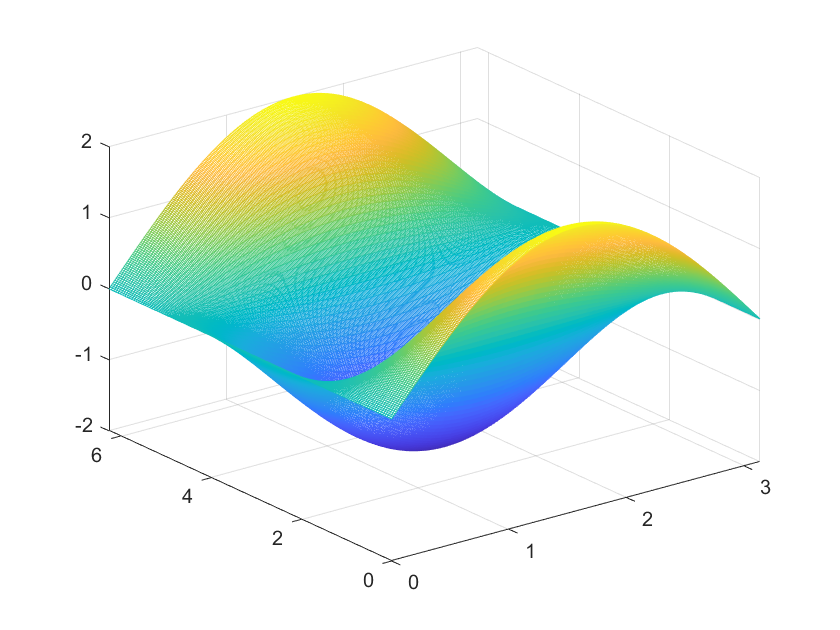

t=0:0.01:pi;r=0:0.05:2*pi;
[T,R]=meshgrid(t,r);
X=2*sin(T).*cos(R);
Y=2*sin(T).*sin(R);
Z=2*cos(T);

mesh(T,R,X)

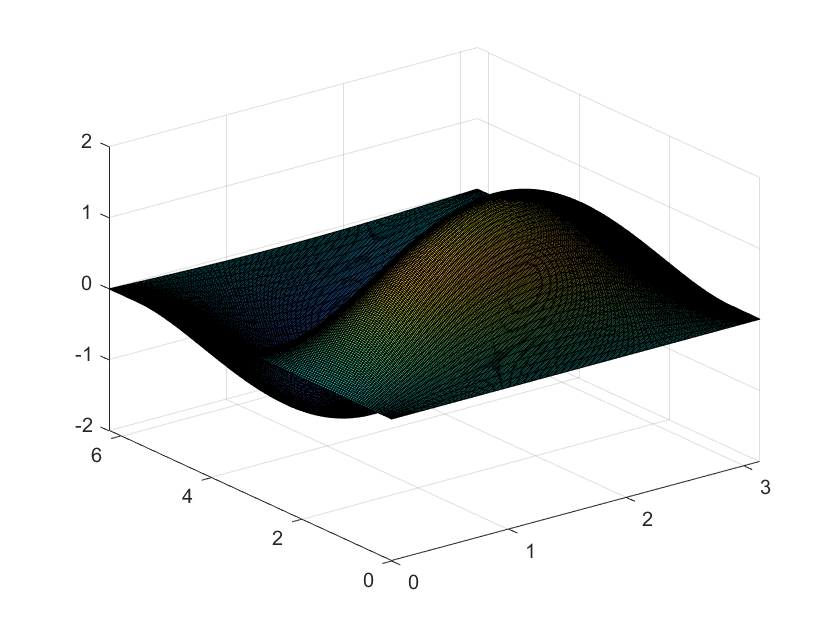

surf(T,R,Y)

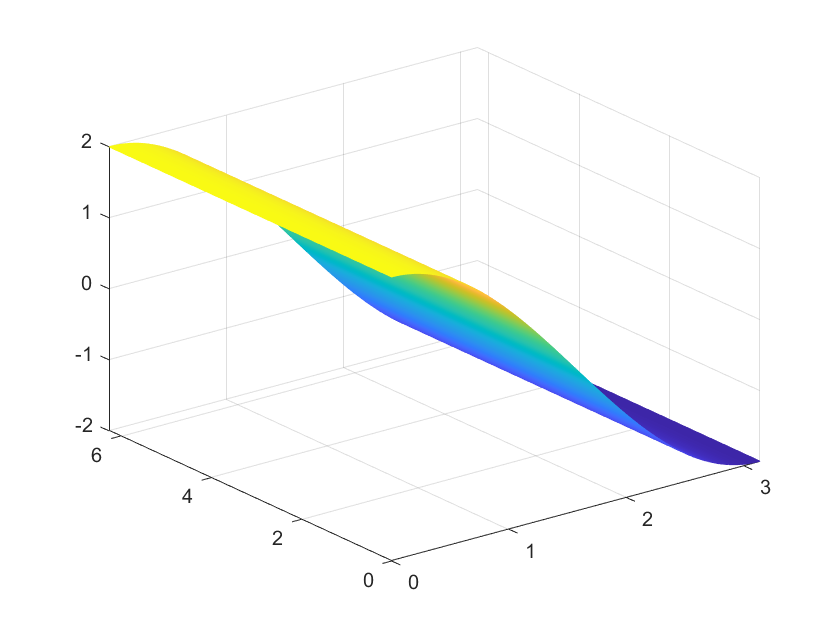

mesh(T,R,Z)

例3.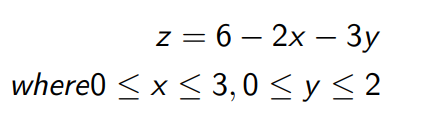

#### find()找点

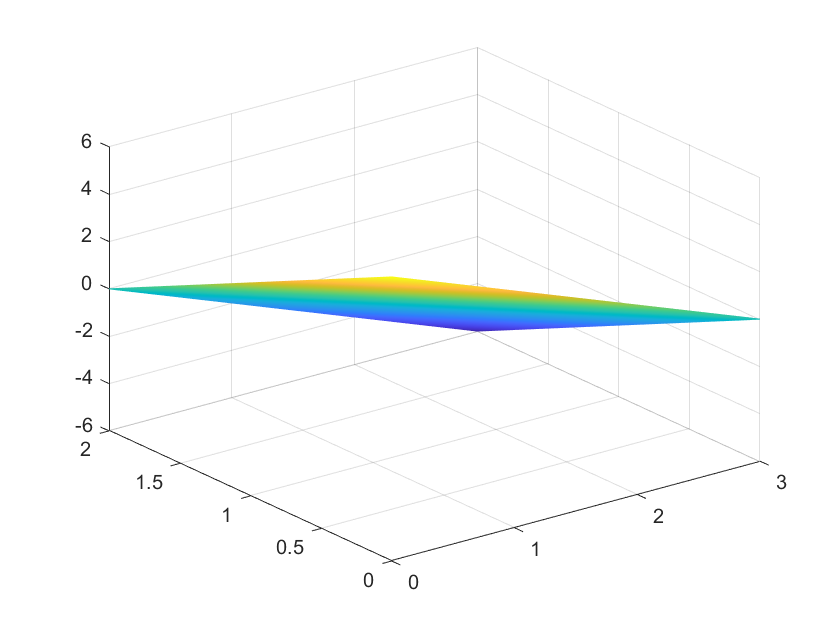

x=0:0.01:3;y=0:0.05:2;
[X,Y]=meshgrid(x,y);
Z=6-2*X-3*Y;
mesh(X,Y,Z)

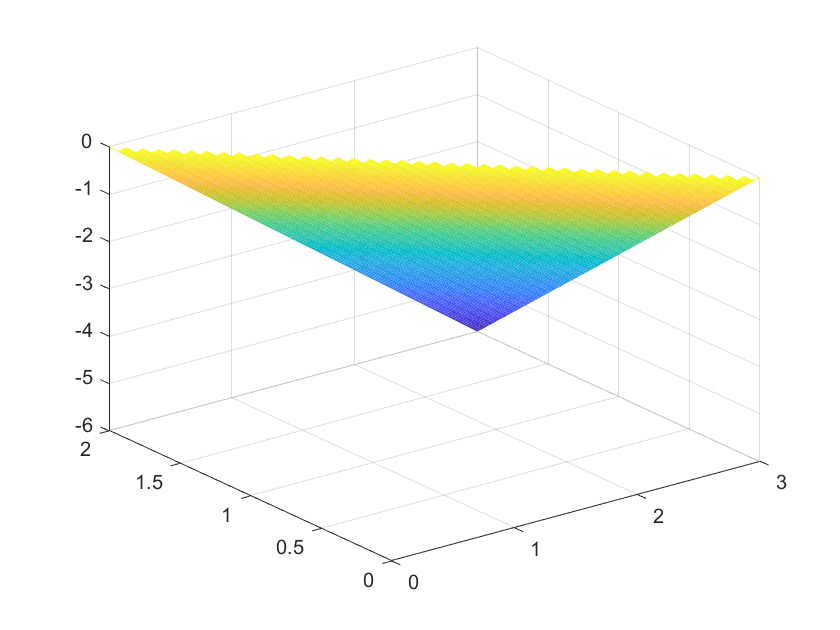


%实现只化Z>0的部分
clf;
idx=find(Z>0);
Z(idx)=NaN;
mesh(X,Y,Z)

## 3D绘图练习1.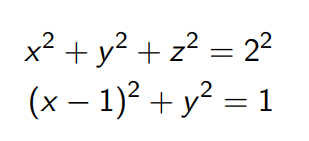

### 5.fimplicit3(f,[a,b])--绘制三维隐函数

fimplicit3(f)

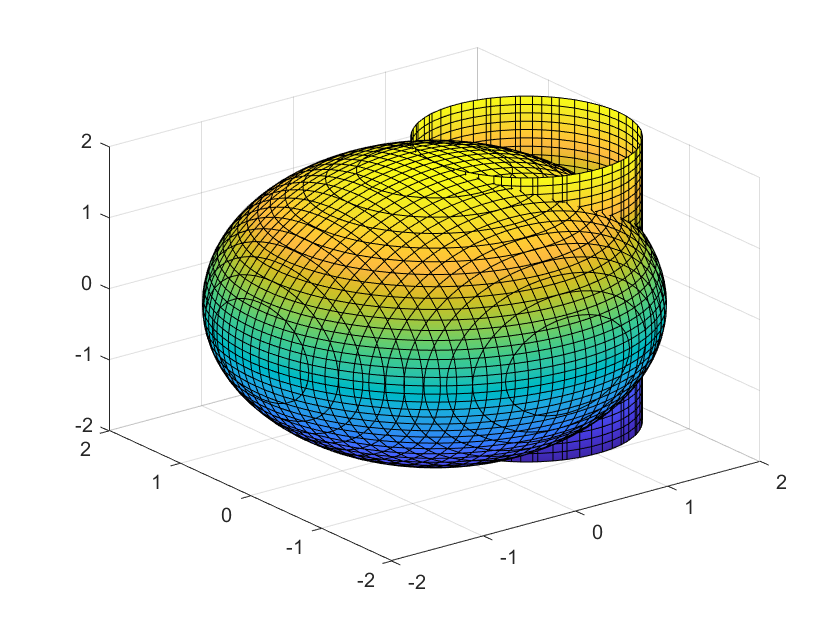

clf
syms x y z
fimplicit3(x^2+y^2+z^2-4,[-2,2])
hold on
fimplicit3((x-1)^2+y^2-1,[-2,2])

练习2.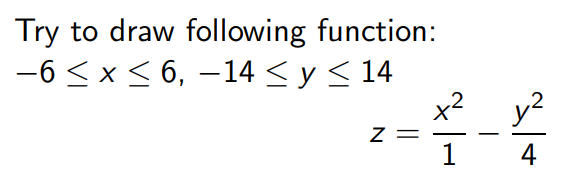

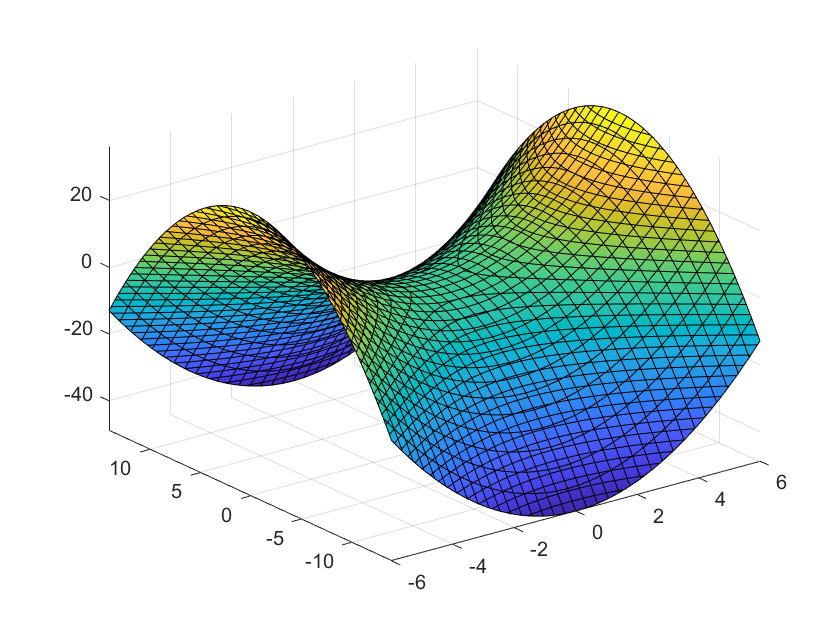

clf;
syms x y z
interval = [-6 6 -14 14 -49 36];%x,y,z的范围
fimplicit3(-x^2+y^2/4+z,interval)

练习3.

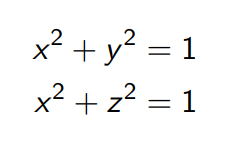

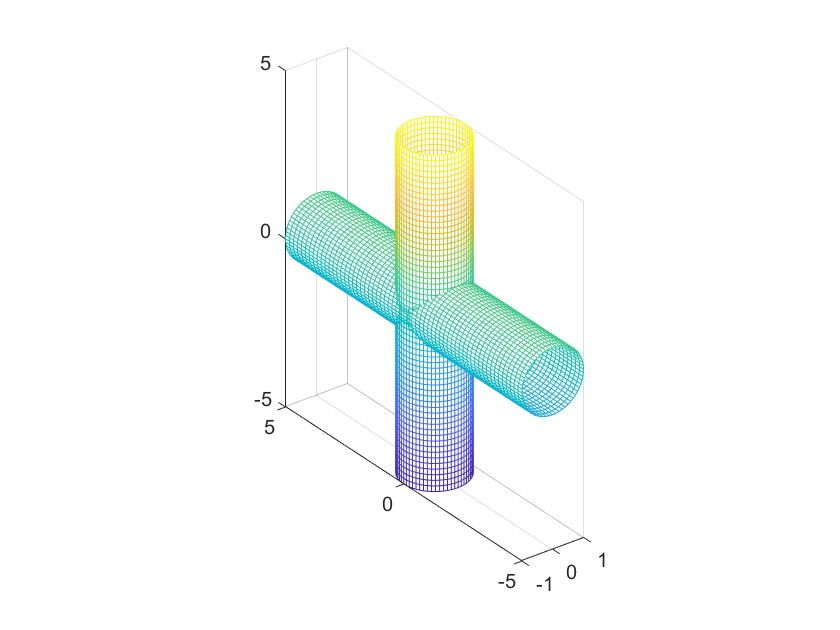

clf
syms x y z
t=0:pi/30:2*pi;
x=sin(t);
y=cos(t);
z=linspace(-5,5,length(t));
X=meshgrid(x);Y=meshgrid(y);Z=[meshgrid(z)]';
mesh(X,Y,Z)%第一个圆柱面
hold on

x1=sin(t);
z1=cos(t);
y1=linspace(-5,5,length(t));
X1=meshgrid(x1);Y1=[meshgrid(y1)]';Z1=meshgrid(z1);
mesh(X1,Y1,Z1)%第二个圆柱面
axis equal

练习4.

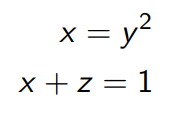

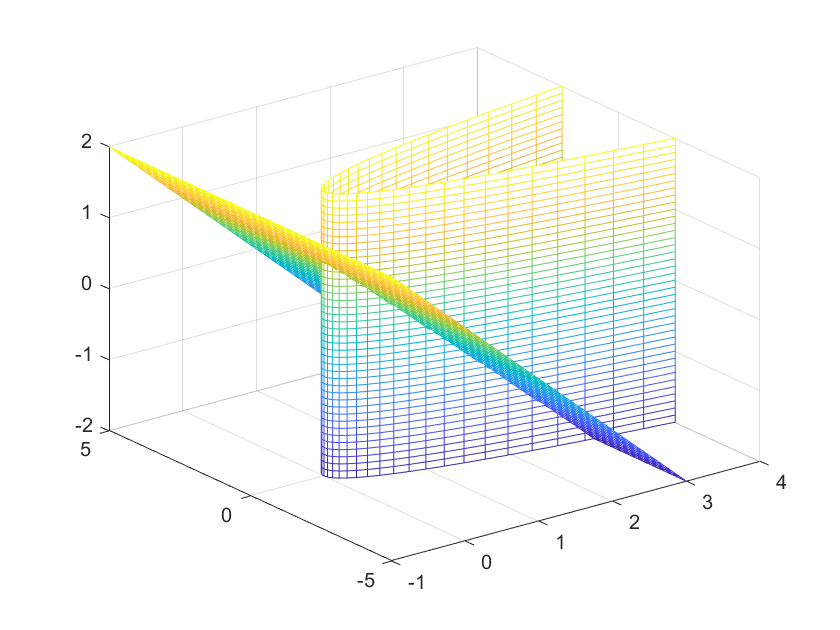

clf
syms x y z
t=-2:0.1:2;
x=t.^2;
y=t;
z=linspace(-2,2,length(t));
X=meshgrid(x);Y=meshgrid(y);Z=[meshgrid(z)]';
mesh(X,Y,Z)%抛物面
hold on

t=-1:0.1:3;
x1=t;
z1=1-t;
y1=linspace(-5,5,length(t));
X1=meshgrid(x1);Y1=[meshgrid(y1)]';Z1=meshgrid(z1);
mesh(X1,Y1,Z1)%切平面